# Machine Learning Online Class - Exercise 2: Logistic Regression

## Initialization

clear ; close all; clc

## Load Data

data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

## ==================== Part 1: Plotting ====================

fprintf(['Plotting data with + indicating (y = 1) examples and o ' ...
         'indicating (y = 0) examples.\n']);

Plotting data with + indicating (y = 1) examples and o indicating (y = 0) examples.


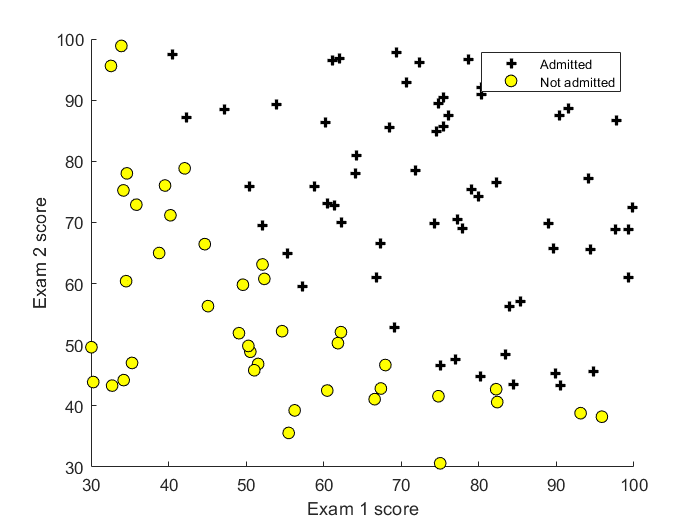


plotData(X, y);

% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
lgd = legend('Admitted', 'Not admitted');
lgd.FontSize = 8;
hold off;


fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


%pause;

## ============ Part 2: Compute Cost and Gradient ============

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X);

% Add intercept term to x and X_test
X = [ones(m, 1) X];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);

fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.000000


fprintf('Expected cost (approx): 0.693\n');

Expected cost (approx): 0.693


fprintf('Gradient at initial theta (zeros): \n');

Gradient at initial theta (zeros): 


fprintf(' %f \n', grad);

 0.000000 
 0.000000 
 0.000000 


fprintf('Expected gradients (approx):\n -0.1000\n -12.0092\n -11.2628\n');

Expected gradients (approx):
 -0.1000
 -12.0092
 -11.2628



% Compute and display cost and gradient with non-zero theta
test_theta = [-24; 0.2; 0.2];
[cost, grad] = costFunction(test_theta, X, y);

fprintf('\nCost at test theta: %f\n', cost);


Cost at test theta: 0.000000


fprintf('Expected cost (approx): 0.218\n');

Expected cost (approx): 0.218


fprintf('Gradient at test theta: \n');

Gradient at test theta: 


fprintf(' %f \n', grad);

 0.000000 
 0.000000 
 0.000000 


fprintf('Expected gradients (approx):\n 0.043\n 2.566\n 2.647\n');

Expected gradients (approx):
 0.043
 2.566
 2.647



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============= Part 3: Optimizing using fminunc =============

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = ...
	fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);

% Print theta to screen
fprintf('Cost at theta found by fminunc: %f\n', cost);
fprintf('Expected cost (approx): 0.203\n');
fprintf('theta: \n');
fprintf(' %f \n', theta);
fprintf('Expected theta (approx):\n');
fprintf(' -25.161\n 0.206\n 0.201\n');

% Plot Boundary
plotDecisionBoundary(theta, X, y);

% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

fprintf('\nProgram paused. Press enter to continue.\n');
pause;

## ============== Part 4: Predict and Accuracies ==============

%  Predict probability for a student with score 45 on exam 1 
%  and score 85 on exam 2 

prob = sigmoid([1 45 85] * theta);
fprintf(['For a student with scores 45 and 85, we predict an admission ' ...
         'probability of %f\n'], prob);
fprintf('Expected value: 0.775 +/- 0.002\n\n');

% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);
fprintf('Expected accuracy (approx): 89.0\n');
fprintf('\n');